# Sample 5-1

## 周波数解析

単変量畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Fourier analysis

Univariate convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 入力信号 $\{u[n]\}_n
$ 

(Input signal $\{u[n]\}_n
$)

% Input u[n]
u = [1 2 3];

### 線形シフト不変システムのインパルス応答 $\{h[n]\}_n
$ 

(Impulse response of a linear shift-invariant system $\{h[n]\}_n
$)

% Impulse response h[n]
h = [1 1 1]/3;

### 線形シフト不変システムの出力応答$\{v[n]\}_n
$ 

(The linear shift-invariant system response $\{v[n]\}_n
$)

畳み込み演算 (Convolution)

        
$$\{v[n]\}_n=\{h[n]\}_n \ast \{u[n]\}_n = \sum_{k=-\infty}^{\infty}u[k]\{h[n-k]\}_n
$$


% Output v[n]
v = conv(h,u);

### 入力信号 $\{u[n]\}_n
$ のスペクトル

(Spectrum of input signal $\{u[n]\}_n
$)

        
$$U(e^{\j\omega})= \sum_{n=-\infty}^{\infty}u[n]e^{-\j\omega n},\ \omega\in\mathbb{R}$$


DFT(FFT)によるDTFTの周波数サンプル計算 (Frequency sampling of DTFT by DFT (FFT))

        
$$U[k] = \left.U(e^{j\omega})\right|_{\omega=\frac{2\pi }{N}k},\ k\in\{0,1,2,\cdots,N-1\}$$


% Setting the number of frequency sample points in [0,2π)
nPoints = 128;

% Spectrum of u[n]
U = fft(u,nPoints);

### フィルタ $\{h[n]\}_n
$ の周波数応答

(Frequency response of filter$\{h[n]\}_n
$)

        
$$H(e^{\j\omega})= \sum_{n=-\infty}^{\infty}h[n]e^{-\j\omega n},\ \omega\in\mathbb{R}$$


DFT(FFT)によるDTFTの周波数サンプル計算 (Frequency sampling of DTFT by DFT (FFT))

        
$$H[k] = \left.H(e^{j\omega})\right|_{\omega=\frac{2\pi }{N}k},\ k\in\{0,1,2,\cdots,N-1\}$$


% Frequency response of h[n]
H = fft(h,nPoints);

### 出力信号 $\{v[n]\}_n
$ のスペクトル

(Spectrum of input signal $\{v[n]\}_n
$)

        
$$V(e^{\j\omega})= \sum_{n=-\infty}^{\infty}v[n]e^{-\j\omega n},\ \omega\in\mathbb{R}$$


DFT(FFT)によるDTFTの周波数サンプル計算 (Frequency sampling of DTFT by DFT (FFT))

        
$$V[k] = \left.V(e^{\j\omega})\right|_{\omega=\frac{2\pi }{N}k},\ k\in\{0,1,2,\cdots,N-1\}$$


% Frequency response of v[n]
V = fft(v,nPoints);

### スペクトルと周波数応答の表示

(Display of spectra and frequency response)

        
$$V(e^{\j\omega})=H(e^{\j\omega})U(e^{\j\omega})$$


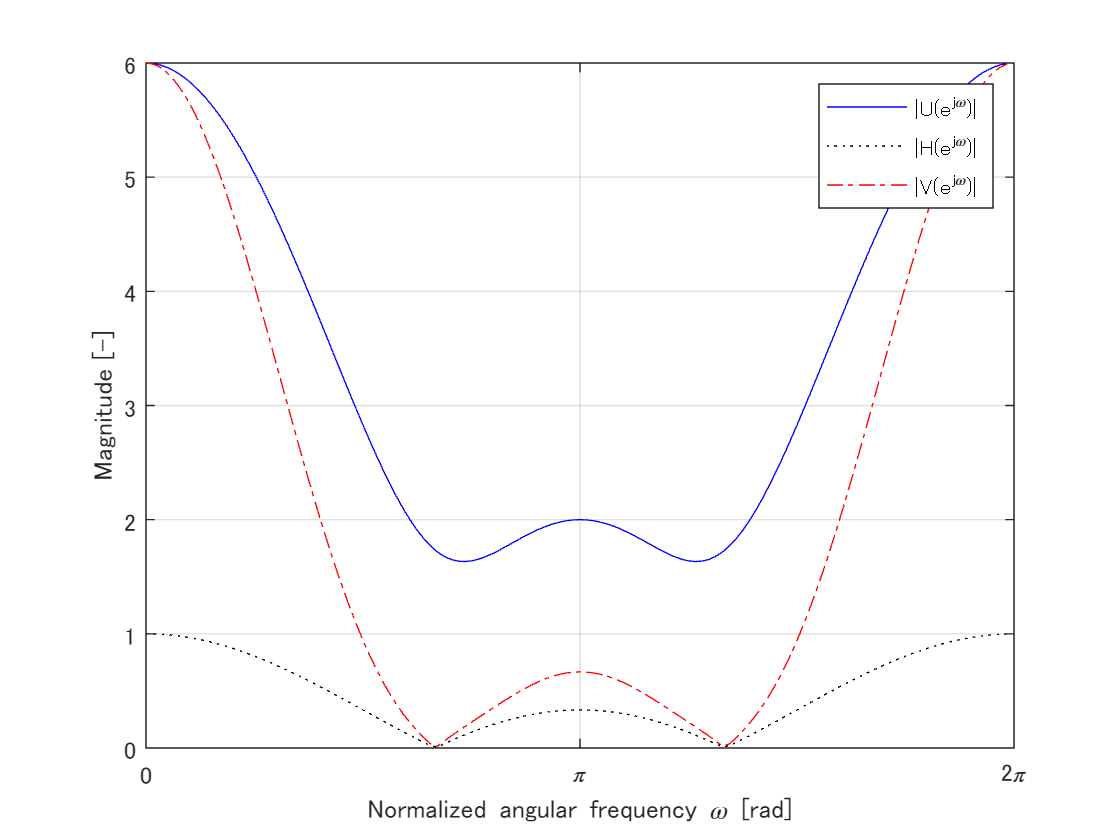

% Frequency sample points 
w = 0:2*pi/nPoints:2*pi-1/nPoints;

% Display of spectra and frequency response
figure(1)
ax = gca;
plot(ax,w,abs(U),'b',w,abs(H),'k:',w,abs(V),'r-.')
grid(ax,'on')
xlabel(ax,'Normalized angular frequency \omega [rad]')
ylabel(ax,'Magnitude [-]')
legend(ax,'|U(e^{j\omega})|','|H(e^{j\omega})|','|V(e^{j\omega})|')
ax.XLim = [0 2*pi];
ax.XTick = [0 pi 2*pi];
ax.XTickLabel = {'0', '\pi', '2\pi' };

### 線形シフト不変システムの解析

(Analysis of linear shift-invariant systems)

#### インパルス応答

(Impulse respone)

         
$$h[n],\ n\in\mathbb{Z}
$$
 

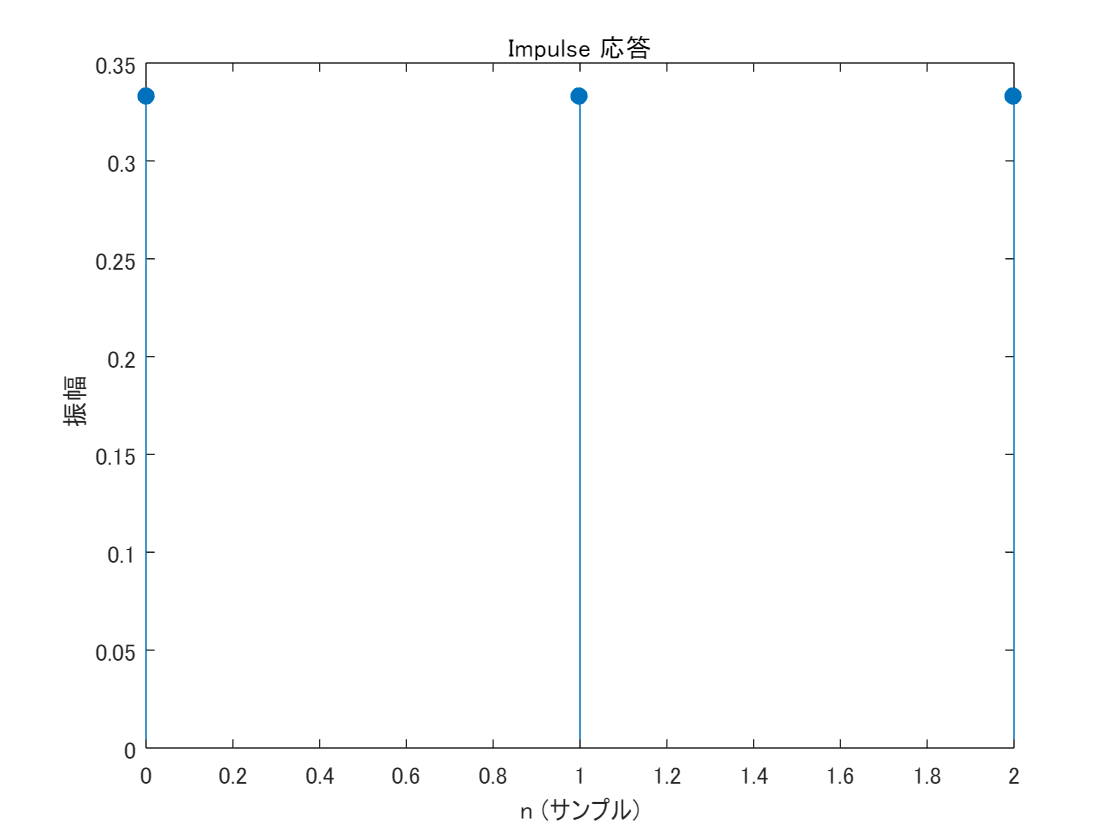

figure(2)
impz(h)

#### 伝達関数

(Transfer function)

        
$$H(z)= \sum_{n=-\infty}^{\infty}h[n]z^{-n},\ z\in\mathbb{C}$$


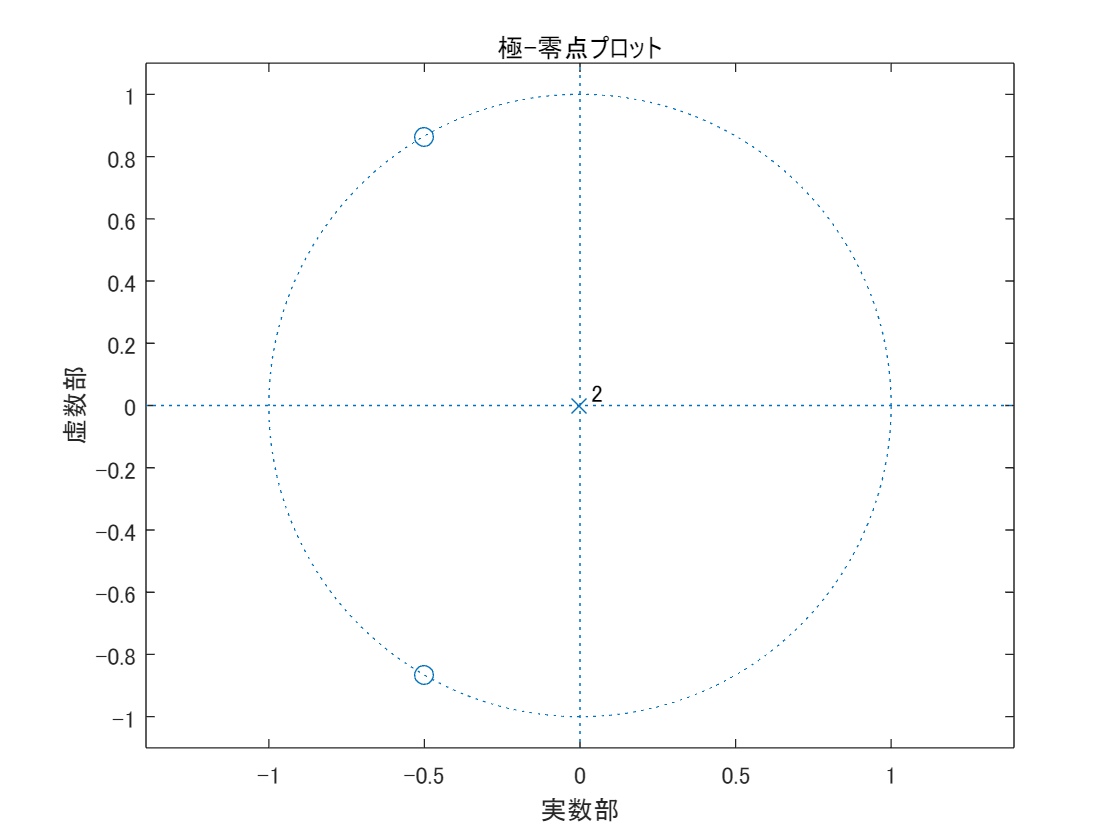

figure(3)
zplane(h)

#### 周波数応答

(Frequency response)

        
$$H(e^{\j\omega})= \left.H(z)\right|_{z=e^{\j\omega}},\ \omega\in \mathbb{R}$$


- 振幅応答 (Magnitude response): $|H(e^{\j\omega})|$

- 位相応答 (Phase response): $\angle H(e^{\j\omega})$

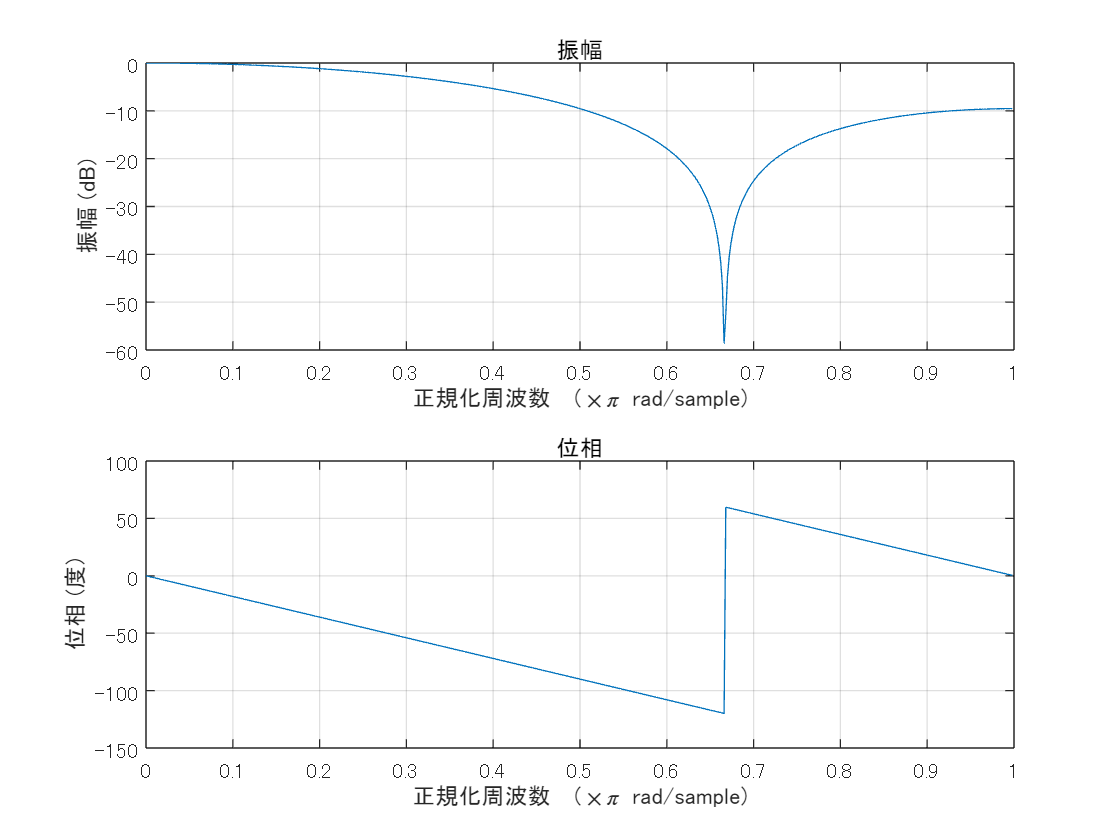

figure(4)
freqz(h)

© Copyright, Shogo MURAMATSU, All rights reserved.